## CT Reconstruction

clc;
clear all;
close all;

### Load the projection data

The projection dataset that is loaded below contains all of the CT projections calculated from a simulated model of a mouse in a simulated CT scanner. Since the projections were generated compuationally, there is little benefit to reducing the size of the projections dataset. However, for real life CT scans, decisions must be made about the best way to sample the projections for a limited acquisition time or patient dose.

Assume that the CT scanner that is being simulated has a detector with an array of 380 elements and that at each axial position 180 images are recorded at 1-180 degrees (i.e. matching the 'CT projections.mat' dataset). Thus a single axial slice can be reconstructed, and then the scanner is moved to the next axial position up to a total of 190 axial locations.

Your task is to evaluate different stragies of sampling the projections such that only 1/10th of the total data within 'CT projections.mat' is used, achieving a speedup of approximately x10 in acquisition time. For simplicity we will only be considering the 140th slice in this practice.

load('CT projections.mat');

### Test 1

Using the raw data in ‘*CT projections.mat*’, preview the sinogram for 140th axial slice. The sinogram will have dimensions 380 (projection coordinate) x 180 (projection angle). For the double for loop shown in the script fill in the missing line to form the 140th sinogram and save the image as ‘TASK_1_CT_SINOGRAM.png’. Alternatively you can delete the for loop and directly index the data you need from within the projections. Complete a filtered and an unfiltered backprojection and save the images as 'TASK_1_CT_FILTERED_BP.png' and 'TASK_1_CT_UNFILTERED_BP.png' respectively.

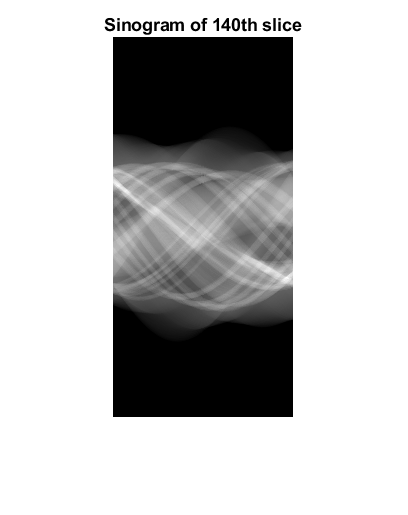

p=1:1:180;      %angles
[~,nop]=size(p);
sinogram140=zeros(380,nop);

for i=1:nop %angle
   for j=1:380 %projection coordinate
        %%%Insert missing code here
        sinogram140(j,i)=projections(140,j,i);  
   end
end
fig1=figure;
imshow(sinogram140,[]);
title('Sinogram of 140th slice')
saveas(fig1,'TASK_1_CT_SINOGRAM.png'); 

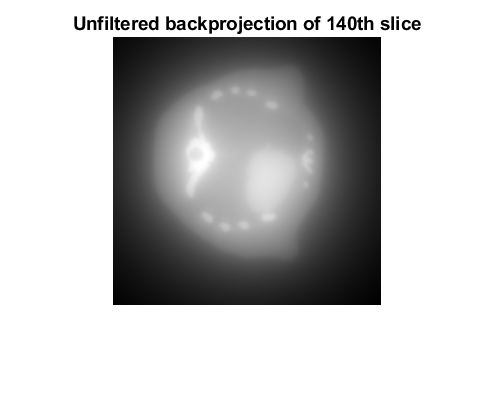


%Unfiltered backprojection of 140th slice
UnfilteredBackprojection=iradon(sinogram140,p,'linear','none');
figure;
fig2=imshow(UnfilteredBackprojection,[]);
hold on;
title('Unfiltered backprojection of 140th slice')
saveas(fig2,'TASK_1_CT_UNFILTERED_BP.png');

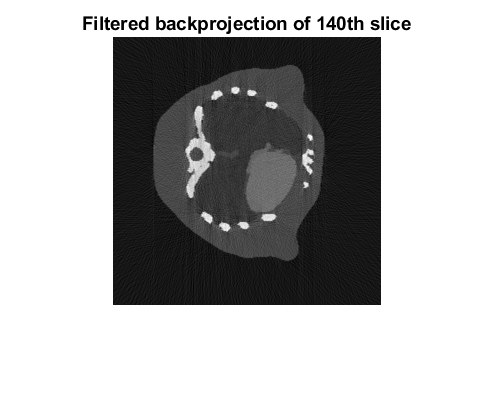


%Filtered backprojection of 140th slice
FilteredBackprojection=iradon(sinogram140,p); 
figure;
fig3=imshow(FilteredBackprojection,[]); 
hold on;
title('Filtered backprojection of 140th slice') 
saveas(fig3,'TASK_1_CT_FILTERED_BP.png'); 

### Test 2

Calculate the sinogram, filtered and unfiltered backprojections for the 140th slice using only 1/10th of the projection data such that only neighbouring angles are used, i.e. a wedge shaped range of projection angles. Save your three images with similar names as for Task 1, substituting '1' for '2' in the file names.

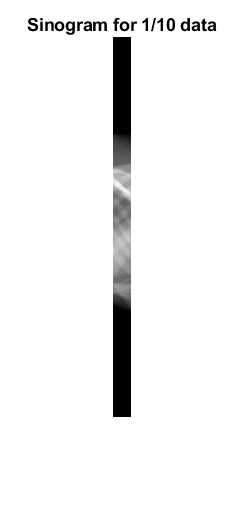

p2=1:1:18;  %angles
[~,nop2]=size(p2);
sinogram140_onetenth=zeros(380,nop2);
for i=1:nop2 %angle
    for j=1:380 %projection coordinate
         sinogram140_onetenth(j,i)=projections(140,j,i);
    end
end
fig4=figure;   
imshow(sinogram140_onetenth,[]);
title('Sinogram for 1/10 data')
saveas(fig4,'TASK_2_CT_SINOGRAM.png'); 

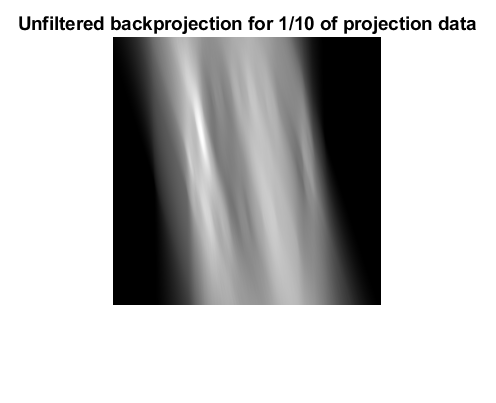


%Unfiltered backprojection for 1/10 of projection data
UnfilteredBackprojection_onetenth=iradon(sinogram140_onetenth,p2,'linear','none');
figure;
fig5=imshow(UnfilteredBackprojection_onetenth,[]);
hold on;
title('Unfiltered backprojection for 1/10 of projection data')
saveas(fig5,'TASK_2_CT_UNFILTERED_BP.png');

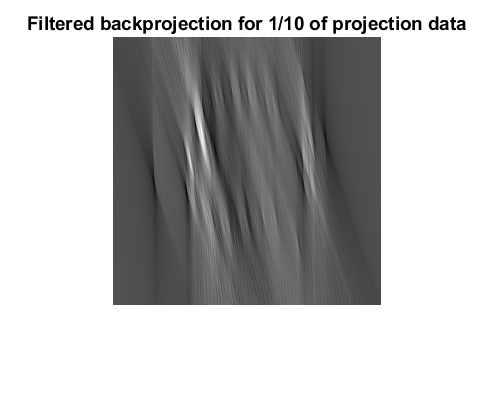


%Filtered backprojection for 1/10 of projection data
FilteredBackprojection_onetenth=iradon(sinogram140_onetenth,p2); 
figure;
fig6=imshow(FilteredBackprojection_onetenth,[]); 
hold on;
title('Filtered backprojection for 1/10 of projection data') 
saveas(fig6,'TASK_2_CT_FILTERED_BP.png'); 

### Test 3

Calculate the sinogram, filtered and unfiltered backprojections for the 140th slice using only 1/10th of the projection data such that these angles are equally spaced over the available projections. Save your three images as above.

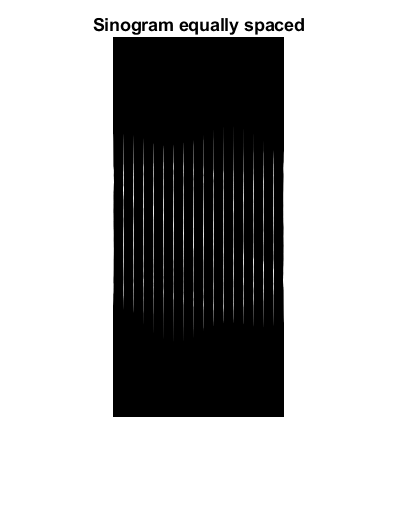

p3=1:10:180;  %angles
[~,nop3]=size(p3);
sinogram140_equalspace=zeros(380,nop3);
for i=p3 %angle
    for j=1:380 %projection coordinate
         sinogram140_equalspace(j,i)=projections(140,j,i);
    end
end
fig7=figure;   
imshow(sinogram140_equalspace,[]);
title('Sinogram equally spaced')
saveas(fig7,'TASK_3_CT_SINOGRAM.png'); 

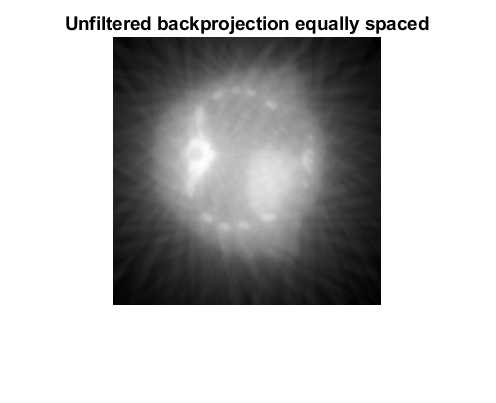

p3_range=1:1:max(1:10:180);

%Unfiltered backprojection equally spaced
UnfilteredBackprojection_equalspace=iradon(sinogram140_equalspace,p3_range,'linear','none');
figure;
fig8=imshow(UnfilteredBackprojection_equalspace,[]);
hold on;
title('Unfiltered backprojection equally spaced')
saveas(fig8,'TASK_3_CT_UNFILTERED_BP.png');

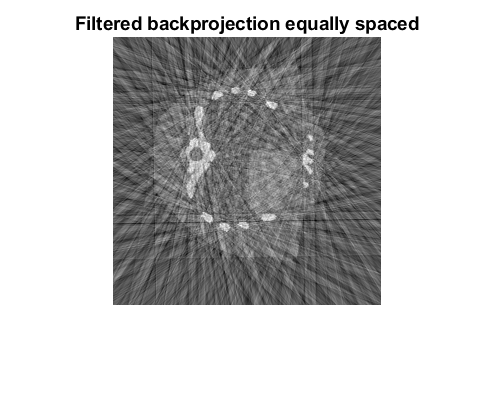


%Filtered backprojection equally spaced
FilteredBackprojection_equalspace=iradon(sinogram140_equalspace,p3_range); 
figure;
fig9=imshow(FilteredBackprojection_equalspace,[]); 
hold on;
title('Filtered backprojection equally spaced') 
saveas(fig9,'TASK_3_CT_FILTERED_BP.png'); 

### Test 4

Simulate the acquisition of a spiral CT dataset and reconstruct the sinogram, filtered and unfiltered backprojections for the 140th slice. You should use a pitch of 18, i.e. there are 18 neighbouring projection angles acquired for each axial position. Due to the axial translation of the scan bed the next 18 angles will be acquired for the neighbouring axial position, i.e. only 10th of the available data is used for the reconstruction of the 140th slice, but over different axial positions. Save your images as above. Explain your approach to this task in the Word document as well as commenting on the result.

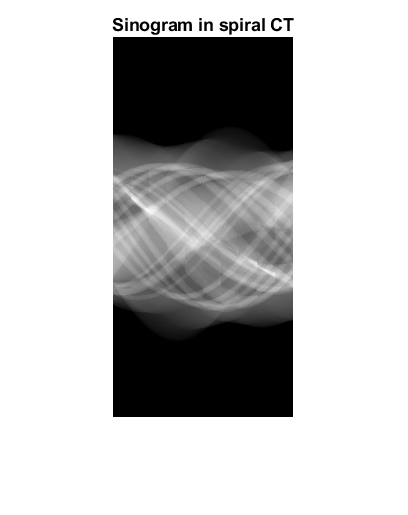

p_spiral=1:1:180;      %angles
[~,nop_spiral]=size(p_spiral);
sinogram_spiral=zeros(380,180);
p_plus=0; %initial value of progressive angle
for k=135:1:144 %10 slices for reconstruction 
   for j=1:380 %projection coordinate
       for i=1:18 %starting angle of the 10 slices
           sinogram_spiral(j,i+p_plus)=projections(k,j,i+p_plus); 
       end
   end
   p_plus=p_plus+18; %progress for 18 degrees per slice
   if i==180
      p_plus=0; %reset when angle reaches 180
   end
end
fig10=figure;
imshow(sinogram_spiral,[]);
title('Sinogram in spiral CT')
saveas(fig10,'TASK_4_CT_SINOGRAM.png'); 

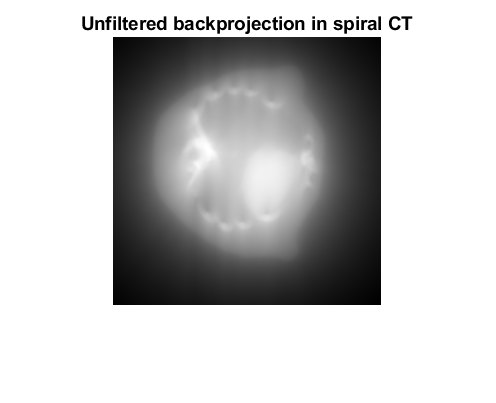


%Unfiltered backprojection in spiral CT
UnfilteredBackprojection_spiral=iradon(sinogram_spiral,p_spiral,'linear','none');
figure;
fig11=imshow(UnfilteredBackprojection_spiral,[]);
hold on;
title('Unfiltered backprojection in spiral CT')
saveas(fig11,'TASK_4_CT_UNFILTERED_BP.png');

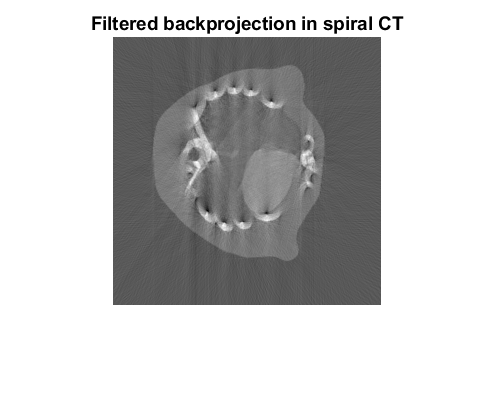


%Filtered backprojection in spiral CT
FilteredBackprojection_spiral=iradon(sinogram_spiral,p_spiral); 
figure;
fig12=imshow(FilteredBackprojection_spiral,[]); 
hold on;
title('Filtered backprojection in spiral CT') 
saveas(fig12,'TASK_4_CT_FILTERED_BP.png'); 